# `Activity 2.2`

## `Analysis of Instruments in 2D and 3D space`

fs = 44100;
[y1,~] = audioread("andean-flute-theme-low_fybeqsnu1.mp3");
[y2,~] = audioread("zo_-pripyati-gitara.mp3");
[y3,~] = audioread("cirk-barabannaya-drob-i-marsh_-silachi.mp3");
[y4,~] = audioread("jamaican-piano_mytjcqbd.mp3");
[y5,~] = audioread("violin-trill_mk15cun_.mp3");
[y6,~] = audioread("z_uk-truba.mp3");

n_samples = 6

n_samples = 6

range = 1000

range = 1000

start = 2*fs;
flute = create_sample_data(y1(:,1),n_samples,range,start);
gitar = create_sample_data(y2(:,1),n_samples,range,start);
drum  = create_sample_data(y3(:,1),n_samples,range,start);
piano = create_sample_data(y4(:,1),n_samples,range,start);
violin = create_sample_data(y5(:,1),n_samples,range,start);
trumpt = create_sample_data(y6(:,1),n_samples,range,start);

### `PCA`

x = [flute,gitar,drum,piano,violin,trumpt];
m = mean(x')';
xmr = x-m;
s = cov(xmr');
[V,D] = eigs(s,10);
ymr = V'*xmr;
y = ymr;

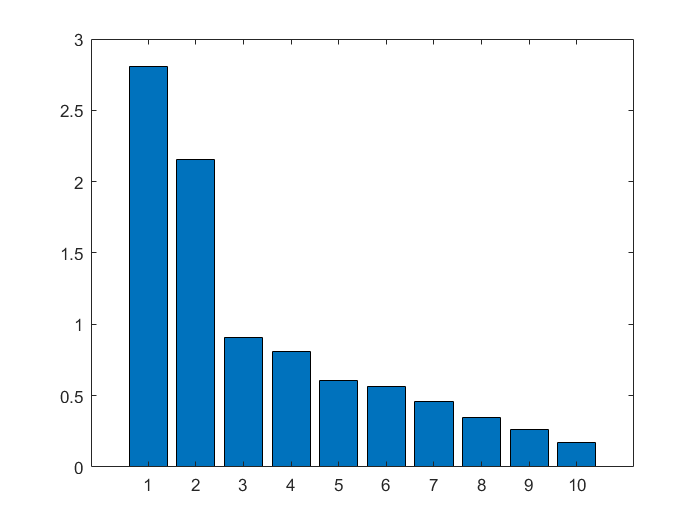

bar(diag(D))

ymr = V'*xmr;
y = ymr;

flute_range = 1:6;
gitar_range = 7:12;
drum_range  = 13:18;
piano_range = 19:24;
violin_range = 25:30;
trumpt_range = 31:36;

#### `Visualize in 2D`

scatter_size = 50

scatter_size = 50

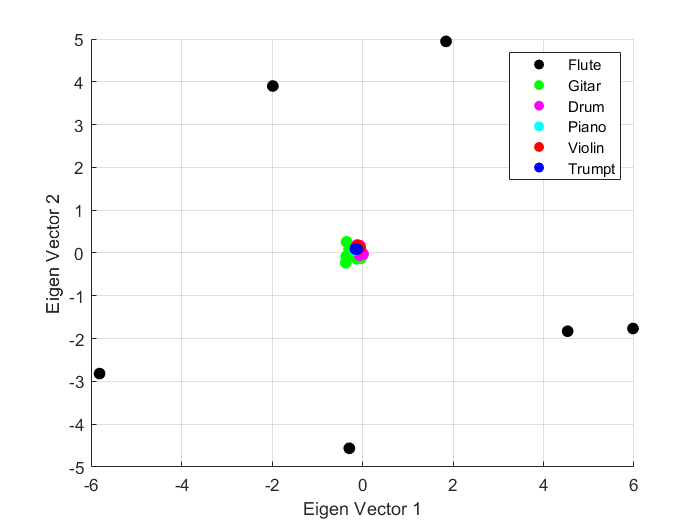

figure()
scatter(y(1,flute_range),y(2,flute_range),scatter_size,'k',"filled",'DisplayName','Flute')
hold on
scatter(y(1,gitar_range),y(2,gitar_range),scatter_size,'g',"filled",'DisplayName','Gitar')
hold on
scatter(y(1,drum_range),y(2,drum_range),scatter_size,'magenta',"filled",'DisplayName','Drum')
hold on
scatter(y(1,piano_range),y(2,piano_range),scatter_size,'cyan',"filled",'DisplayName','Piano')
hold on
scatter(y(1,violin_range),y(2,violin_range),scatter_size,'r',"filled",'DisplayName','Violin')
hold on
scatter(y(1,trumpt_range),y(2,trumpt_range),scatter_size,'b',"filled",'DisplayName','Trumpt')
grid on
xlabel('Eigen Vector 1')
ylabel('Eigen Vector 2')
legend()

#### `Visualize in 3D`

scatter_size = 50

scatter_size = 50

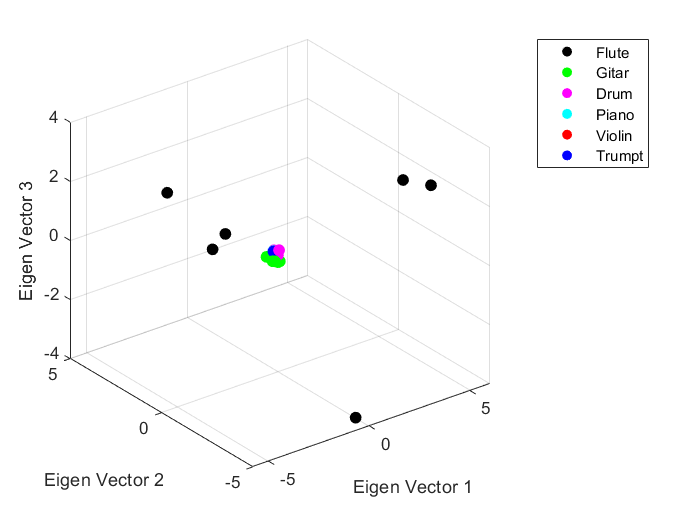

figure()
scatter3(y(1,flute_range),y(2,flute_range),y(3,flute_range),scatter_size,'k',"filled",'DisplayName','Flute')
hold on
scatter3(y(1,gitar_range),y(2,gitar_range),y(3,gitar_range),scatter_size,'g',"filled",'DisplayName','Gitar')
hold on
scatter3(y(1,drum_range),y(2,drum_range),y(3,drum_range),scatter_size,'magenta',"filled",'DisplayName','Drum')
hold on
scatter3(y(1,piano_range),y(2,piano_range),y(3,piano_range),scatter_size,'cyan',"filled",'DisplayName','Piano')
hold on
scatter3(y(1,violin_range),y(2,violin_range),y(3,violin_range),scatter_size,'r',"filled",'DisplayName','Violin')
hold on
scatter3(y(1,trumpt_range),y(2,trumpt_range),y(3,trumpt_range),scatter_size,'b',"filled",'DisplayName','Trumpt')
grid on
xlabel('Eigen Vector 1')
ylabel('Eigen Vector 2')
zlabel('Eigen Vector 3')
legend()

function sample = create_sample_data(data_array,n_samples,range,start)
    sample = zeros(range,n_samples);
    for i=1:n_samples
        range_sample = (i-1)*range+1 : i*range;
        range_data = ((i-1)*range+1)+start : (i*range)+start;
        sample(range_sample) = data_array(range_data);
    end
end